# ;Energy Consumption Simulation

## 使い方

- vehicle_parameter_nit00.mlxでパラメータ設定

- GGV_map_creation_4.mlxで車両のGGV Mapを作成

- 走るコースを決め，Lap Time Simulation !

一度，GGV Mapを作成した車両に関しては，保存されている

GGV_Map_nit00_00.matを読み込んでシミュレーションするので，

1, 2を行う必要はありません

### 注意事項

コースのエクセルはすでにあるものと，まったく同じように作成してください

### 計算結果は一番下に表示されます

### シミュレーション条件設定

%%コースデータ読み込み

% コメントアウトを変更してコースを変更
% trackfile = 'nit23_ecopa_50_kawai.xlsx'; % ecopa 50kW
% trackfile = 'nit23_ecopa_endurance_kawai.xlsx'; % ecopa 30kW
trackfile = 'nit23_ASE_endurance_kawai.xlsx'; % ASE Endurance 30kW
% trackfile = 'nit23_ASE_autoX_kawai.xlsx'; %ASE Auto X 50kW

%% 走行車両GGV Map
% vehicle_name = 'nitXX'; % 車両名 図を保存するときにタイトルになる
% vehicle_sim = 'GGV_map_nitXX.mat'; % 要変更 車両GGV Map
vehicle_name = 'nit23_50'; % 車両名 図を保存するときにタイトルになる
vehicle_sim = 'GGV_map_nit23_50.mat'; % 要変更 車両GGV Map

%% スタート地点での速度(0以外)
start_v = 47; % [km/h]

%% ドライバー練度
driver = 1.06; %タイム再現性
driver_acc = 0.8; %ドライバーの加速のうまさ
driver_dec = 0.8; %ドライバーの減速のうまさ
driver_cor = 0.9; %ドライバーのコーナリングのうまさ

%% --- パラメータ設定 ---
V_sys = 400;            % [V] システム電圧
I_chg_limit = 20;       % [A] 回生制限電流
battery_cap_kWh = 7.104;% バッテリー容量 [kWh]
num_laps = 20;          % エンデュランスの周回数（コース長に合わせて調整）

%% 仮想敵
% 名古屋大学
nu_time = 73; %Endurance ave. time
nu_eff = 6; %kWh
% Jillin univ.
jil_time = 73;
jil_eff = 6.38;
% 東京大学
ut_time = 76;
ut_eff = 5.34;
% 効率大学
efu_time = 100;
efu_eff = 1.98;

% 格納
Enemy_time = [nu_time*num_laps, jil_time*num_laps, ut_time*num_laps, efu_time*num_laps];
Enemy_eff = [nu_eff, jil_eff, ut_eff, efu_eff];

### コース設定

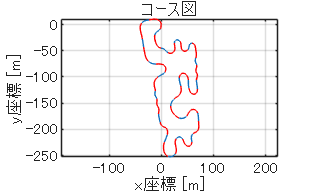

% -----------------------------------------------------------
% ここから下はラップタイムシミュレーションを行うセクションです
% 修正を加える場合は中身を理解した上で行ってください
% -----------------------------------------------------------

%コース読み込み
trackdata = readmatrix(trackfile, 'Range', 'C18'); % ExcelのC18より右下をすべて抜き出す

lat = trackdata(:,5); % trackdataの経度
lon = trackdata(:,4); % trackdataの緯度
origin = [lon(1),lat(1),0]; % 原点をスタート地点に設定
[x,y] = latlon2local(lon, lat, 0, origin); % 緯度経度→デカルト座標
plot(x,y)
grid on
title("コース図");
xlabel("x座標 [m]")
ylabel("y座標 [m]")
axis equal; % xyを1:1にする

% 累積距離を計算
dist = [0; cumsum(sqrt(diff(x).^2 + diff(y).^2))];

% 0.5m間隔の距離ベクトルを作成
s_interp = (0:0.5:dist(end))';

% 三次スプラインで座標をリサンプリング
x_smooth = interp1(dist, x, s_interp, 'spline');
y_smooth = interp1(dist, y, s_interp, 'spline');
v_smooth = interp1(dist, trackdata(:,3), s_interp, 'spline');

% 確認用プロット
hold on;
plot(x_smooth, y_smooth, 'r--'); % 滑らかになったライン
hold off


% グラディエントを計算
dx  = gradient(x_smooth, 0.5);
ddx = gradient(dx, 0.5);
dy  = gradient(y_smooth, 0.5);
ddy = gradient(dy, 0.5);

% 曲率の公式
kappa = (dx.*ddy - dy.*ddx) ./ (dx.^2 + dy.^2).^(1.5);

% ノイズが残る場合はさらに移動平均
kappa = smoothdata(kappa, 'gaussian', 5);

% 各点間の距離を再計算
ds = [0; sqrt(diff(x_smooth).^2 + diff(y_smooth).^2)];

% 累積距離ベクトル (これが速度プロファイルの横軸になります)
s_accumulated = cumsum(ds);

% 全走距離（コース長）
total_length = s_accumulated(end);
fprintf('コース長: %.2f m\n', total_length);

コース長: 971.42 m


### ラップタイムシミュレーション

load(vehicle_sim); % GGV Map読み込み

% 単位変換
G2MS = 9.80665;
KMH2MS = 1/3.6;

% GGVデータの単位変換と準備
ax_map = GGV(:,:,1) * G2MS; 
ay_map = GGV(:,:,2) * G2MS;
v_map  = GGV(:,:,3) * KMH2MS; 

% 加速側の補間関数
ax_map_acc = ax_map(:,1:44); % GGV Map中の加速のみ
ay_map_acc = ay_map(:,1:44);
v_map_acc = v_map(:,1:44);
F_acc = scatteredInterpolant(ay_map_acc(:)*driver_acc, v_map_acc(:), ax_map_acc(:));

% 減速側の補間関数
ax_map_dec = ax_map(:,45:88); % GGV Map中の減速のみ
ay_map_dec = ay_map(:,45:88);
v_map_dec = v_map(:,45:88);
F_dec = scatteredInterpolant(ay_map_dec(:)*driver_dec, v_map_dec(:), ax_map_dec(:)); % ここ警告出るけど特に問題ない


v_vec = v_map(:,1); % 速度ベクトル [m/s]
ay_limit_vec = max(abs(ay_map), [], 2)*driver_cor; % 各速度での最大横G [m/s^2]

% 旋回限界速度 (V_limit) の計算
v_limit = zeros(size(kappa));
v_test = linspace(0.1, max(v_vec), 200); % 探索用の速度軸

for i = 1:length(kappa)
    if abs(kappa(i)) < 1e-4 % 曲率がすごく小さいとき
        v_limit(i) = max(v_vec); % 直線区間
    else
        % 必要横G (v^2 * kappa) と車両限界を照合
        ay_req = (v_test.^2) * abs(kappa(i)); % 必要G
        ay_max_at_v = interp1(v_vec, ay_limit_vec, v_test, 'linear', 'extrap'); % 車両限界を線形補間で求める

        idx = find(ay_req <= ay_max_at_v, 1, 'last'); % 最大を探索
        if isempty(idx)
            % もし一つも見つからない（極低速でも曲がれない）場合は、
            % 探索範囲の最小値を入れることでエラーを防ぐ
            v_limit(i) = v_test(1);
        else
            v_limit(i) = v_test(idx);
        end
    end
end

P_regen_max = V_sys * I_chg_limit; % [W] 8000W
p_limits = (20:2:maxPower) * 1000; % 20kWから50kWまで
Endurance_results = []; % [Power(kW), LapTime(s), TotalEnergy(kWh)]
sim_log_data = [];
k = 1;

for P_limit = p_limits
    % --- 1. Forward Pass (加速制限あり) ---
    v_fwd = zeros(size(s_accumulated));
    v_fwd(1) = start_v * KMH2MS;
    
    energy_acc = 0;
    for i = 1:length(s_accumulated)-1
        v_curr = v_fwd(i);
        ay_req = (v_curr^2 * abs(kappa(i)));

        ay_max_curr = interp1(v_vec, ay_limit_vec, v_curr);
        ay_query = min(ay_req, ay_max_curr * 0.99);
        
        ax_acc = F_acc(ay_query, v_curr);
        ax_acc = max(0, ax_acc); % 加速のみ抽出

        % モーターパワー計算
        df = -0.5*rho*Af*Cl*v_curr^2; % ダウンフォース
        Fxd = 0.5*rho*Af*Cd*v_curr^2; % ドラッグ
        MtrSpd = v_curr*(30/pi)*gearRatio/(0.0254*tireD/2); % モーター回転数

        Trq = ptr_eff*P_limit/(MtrSpd*2*pi/60); % 理論上のモータートルク

        if Trq <= maxTrq       % トルクカット(Yamaha Proto)
            Trqmax = Trq;
        else
            Trqmax = maxTrq;
        end

        Frr_acc = Crr*(9.8*m + df);
        Fx_Mtr = num_motors*Trqmax*gearRatio/(tireD*0.0254/2); % モーター駆動力
        
        % ★パワー制限の適用
        if v_curr > 1.0 
            ax_p_limit = (Fx_Mtr - Fxd -Frr_acc)/m;
            ax_acc = min(ax_acc, ax_p_limit);
        end
        
        v_next = sqrt(v_fwd(i)^2 + 2 * ax_acc * 0.5);
        v_fwd(i+1) = min(v_next, v_limit(i+1));
    end

    % --- 2. Backward Pass (減速) ---
    % Backward Pass (減速限界の計算)
    v_bwd = zeros(size(s_accumulated));
    v_bwd(end) = v_fwd(end);

    for i = length(s_accumulated):-1:2
        v_curr = v_bwd(i);
        ay_req = (v_curr^2 * abs(kappa(i)));

        ay_max_curr = interp1(v_vec, ay_limit_vec, v_curr); % 車両限界を線形補間
        ay_query = min(ay_req, ay_max_curr * 0.99);

        ax_dec = F_dec(ay_query, v_curr); %加速加速度を補間
        ax_dec = min(0, ax_dec); % 減速(負)のみ抽出

        % 速度更新 (逆向き)
        v_prev = sqrt(v_bwd(i)^2 + 2 * abs(ax_dec) * 0.5);
        v_bwd(i-1) = min(v_prev, v_limit(i-1));
    end

    v_final = min(v_fwd, v_bwd);
    ay_sim = (v_final.^2) .* (kappa/G2MS);
    ax_sim = [diff(v_final.^2) / (2 * 0.5)/G2MS; 0]; % [m/s^2]
    
    % --- 3. エネルギー計算 (1周分) ---
    energy_step = zeros(size(ax_sim));
    for j = 1:length(ax_sim)
        P_mech = m * ax_sim(j) * G2MS * v_final(j);
        if P_mech > 0 % 加速中
            energy_step(j) = (P_mech / ptr_eff) * (0.5 / v_final(j)); 
        else % 減速中
            P_regen = min(abs(P_mech) * ptr_eff, P_regen_max); 
            energy_step(j) = -P_regen * (0.5 / v_final(j));
        end
    end

    lap_energy_kWh = sum(energy_step) / (3600 * 1000);
    total_energy_kWh = lap_energy_kWh * num_laps / driver_acc;
    lap_time = sum(ds ./ v_final) * driver;
    lap_time_total = lap_time * num_laps;
    SOC = (battery_cap_kWh - total_energy_kWh)*100/battery_cap_kWh;
    
    Endurance_results = [Endurance_results; P_limit/1000, lap_time, total_energy_kWh, lap_time_total, SOC];
    sim_log_data(:,:,k) = [ds ./ v_final, cumsum(ds), v_final/KMH2MS, ay_sim, ax_sim];
    k = k+1;
end

### スコア計算

for i = 1:length(p_limits)
    % Endurance Score calculation
    Endurance_time = [Endurance_results(i,4), Enemy_time];
    min_ED_time = min(Endurance_time);
    % Efficiency Score
    Eff = [Endurance_results(i,3), Enemy_eff];
    Eff_CO2 = Eff*0.65;
    CO2_min = min(Eff_CO2);
    min_Eff_fact = ((min_ED_time/num_laps)/((min_ED_time*1.45)/num_laps)) * ((CO2_min/num_laps)/((20.02/100)*(total_length/1000)*num_laps/num_laps));

    for j = 1:length(Endurance_time)
        % Endurance Score calculation
        ETS(i,j) = 250*((min_ED_time*1.45/Endurance_time(1,j))-1)/((min_ED_time*1.45/min_ED_time)-1) + 25;
        % Efficiency Score
        Eff_fact(1,j) = ((min_ED_time/num_laps)/(Endurance_time(1,j)/num_laps)) * ((CO2_min/num_laps)/(Eff_CO2(1,j)/num_laps));
    end
    max_Eff_fact = max(Eff_fact);
    for k = 1:length(Eff_fact)
        EffS(i,k) = 100*(Eff_fact(1,k)-min_Eff_fact)/(max_Eff_fact-min_Eff_fact);
    end
end

Score = ETS + EffS;

### 可視化

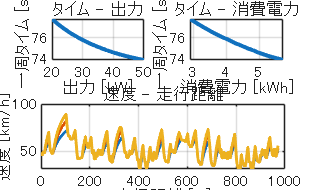

% 図のタイトル作成
current_date = datestr(now, 'yy-mm-dd_HH-MM'); % 非推奨と出るが問題はない
figure_title = [vehicle_name, '_', current_date]; % 車両名 + 日付
figure('Name', figure_title, 'NumberTitle', 'off'); % 図のタイトル

subplot(2,2,1);
plot(Endurance_results(:,1),Endurance_results(:,2),'LineWidth',2);
grid on
xlabel('出力 [kW]')
ylabel('一周タイム [s]')
title('タイム - 出力')

subplot(2,2,2);
plot(Endurance_results(:,3),Endurance_results(:,2),'LineWidth',2);
grid on
xlabel('消費電力 [kWh]')
ylabel('一周タイム [s]')
title('タイム - 消費電力')

subplot(2,2,[3 4]);
for i = 1:6:16
    plot(sim_log_data(:,2,i), sim_log_data(:,3,i),'LineWidth',1.5)
    hold on
    xlabel('走行距離 [m]')
    ylabel('速度 [km/h]')
    title('速度 - 走行距離')
end
grid on